clear all

% 480P videos / behavior file / DLC labels
% video_to_load = 'Do20220225';
video_to_load = 'Do20220302';
% video_to_load = 'Se20220314';
vidPath = ['/mnt/DataDrive2/treeshrew/data_preproc/treeshrew_videos/ObjectRecognition/',video_to_load,'.mp4'];

datfile = './shrewData.mat';

dlcvideo_meta = VideoReader(vidPath);
max_frame = dlcvideo_meta.NumFrames;

RGB = uint8(readFrame(dlcvideo_meta));
clear dlcvideo_meta

Redoing target definition 


Targets are good. 


Redoing target definition 


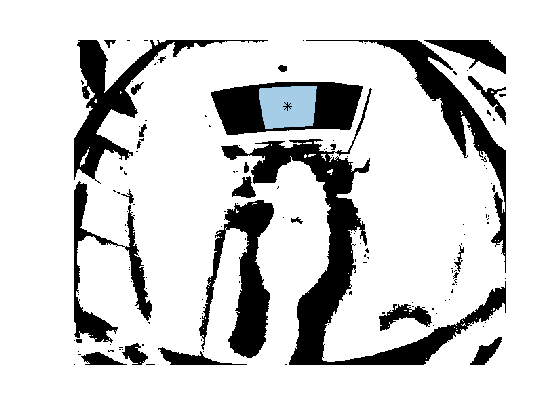

Targets are good. 


[stats_side, stats_cent, mid_side, mid_cent, I_side] = define_mask(vidPath, RGB);


LeftMask = poly2mask(stats_side.ConvexHull{mid_side(1)}(:,1),stats_side.ConvexHull{mid_side(1)}(:,2),size(RGB,1),size(RGB,2));
corners = detectHarrisFeatures(LeftMask,'MinQuality',0.05);
targ_list_left = corners.selectStrongest(4).Location;

RightMask = poly2mask(stats_side.ConvexHull{mid_side(2)}(:,1),stats_side.ConvexHull{mid_side(2)}(:,2),size(RGB,1),size(RGB,2));
corners = detectHarrisFeatures(RightMask);
targ_list_right = corners.selectStrongest(4).Location;

CentMask = poly2mask(stats_cent.ConvexHull{mid_cent(1)}(:,1),stats_cent.ConvexHull{mid_cent(1)}(:,2),size(RGB,1),size(RGB,2));
corners = detectHarrisFeatures(CentMask,'MinQuality',0.05);
targ_list_cent = corners.selectStrongest(4).Location;


clf('reset')
fig3 = figure();
imagesc(uint8(I_side)); %display mean image across entire movie
hold on
scatter(targ_list_left(:,1),targ_list_left(:,2))
scatter(targ_list_right(:,1),targ_list_right(:,2))
% some of the earlier videos were flipped horizontally when uploaded,
% but all recent videos should be fine, i.e. input 'Y'
yn_corners = input('Do the corners look right? Y/N: ','s');
close(fig3);

if strcmp(yn_corners,'N')
    clf('reset')
    fig3 = figure();
    imagesc(uint8(dlcvideo(:,:,:,side_on(ex_tr)))); %display mean image across entire movie
    title('Click on image to identify corners of the left image.')
    [target_x,target_y]=ginput(4);
    target_list_left = [target_x,target_y];
    close(fig3);
    clf('reset')
    fig3 = figure();
    imagesc(uint8(dlcvideo(:,:,:,side_on(ex_tr)))); %display mean image across entire movie
    title('Click on image to identify corners of the right image.')
    [target_x,target_y]=ginput(4);
    target_list_right = [target_x,target_y];
    close(fig3);
end

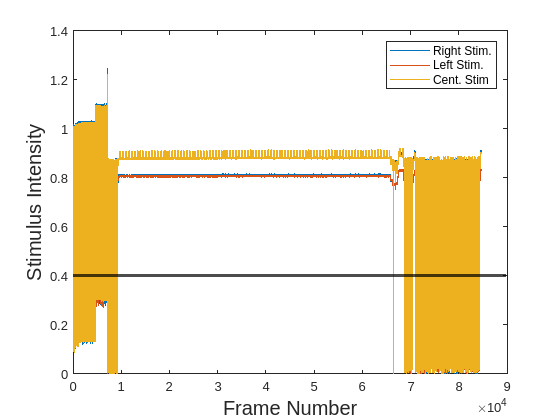

stim_thresh = 0.4;
[side_on, cent_on] = define_trials(vidPath,RightMask,LeftMask,CentMask,stim_thresh);

[dlcFrame_side,dlcFrame_cent,camel_side,imageID] = extract_objects(...
    vidPath,side_on,cent_on,targ_list_right,targ_list_left,targ_list_cent,RightMask,LeftMask);

datafile = ['/mnt/DataDrive2/treeshrew/data_preproc/treeshrew_behavior/Kell_mats/',video_to_load,'_op.mat'];
dat = load(datafile);

target_side = [];
for i = 1:length(dat.opTab.goesRight)
    if isnan(dat.opTab.goesRight(i))
        target_side(i) = NaN;
    elseif dat.opTab.goesRight(i) && dat.opTab.correct(i)
        target_side(i) = 2;
    elseif ~dat.opTab.goesRight(i) && ~dat.opTab.correct(i)
        target_side(i) = 2;
    else
        target_side(i) = 1;
    end
end

% compute a sliding correlation coefficient for both the camel side and
% camel ID
vid_length = length(camel_side);
tr_length = length(target_side);
findcorr_side = nan(vid_length,1);
findcorr_img = nan(vid_length,1);
for i = 1:tr_length - vid_length
    r = corrcoef(camel_side,target_side(i:i+vid_length-1),'rows','complete');
    findcorr_side(i) = r(1,2);
    r = corrcoef(imageID,dat.opTab.T_Expt_ID(i:i+vid_length-1),'rows','complete');
    findcorr_img(i) = r(1,2);
end

% if both methods calculate same trial start index, save this value,
% otherwise use method with higher correlation
if find(findcorr_side==max(findcorr_side))==find(findcorr_img==max(findcorr_img))
    temp = find(findcorr_side==max(findcorr_side));
    tr_idx = temp(1);
    disp(['Video starts at trial: ',num2str(tr_idx)])
elseif max(findcorr_side)>max(findcorr_img)
    temp = find(findcorr_side==max(findcorr_side));
    tr_idx = temp(1);
    disp(['Video starts at trial: ',num2str(tr_idx)])
else
    temp = find(findcorr_img==max(findcorr_img));
    tr_idx = temp(1);
    disp(['Video starts at trial: ',num2str(tr_idx)])
end

Video starts at trial: 61



if strcmp(video_to_load, 'Do20220225')
    trials = [tr_idx:tr_idx+59, tr_idx+61:tr_idx+length(imageID)-1];
    imgtrials = 1:length(imageID)-1;
else
    trials = tr_idx:tr_idx+length(imageID)-1;
    imgtrials = 1:length(imageID);
end
dat_ID = dat.opTab.T_Expt_ID(trials);
dat_correct = dat.opTab.correct(trials);
imageID = imageID(imgtrials);
dlcFrame_side = dlcFrame_side(imgtrials);
camel_side = camel_side(imgtrials);

disp(corr2(dat_ID', imageID))

     1



% only use dlcFrame_side for correct trials
dlcFrame_side = dlcFrame_side(dat_correct==1);
camel_side = camel_side(dat_correct==1);
dat_ID = dat_ID(dat_correct==1);
imageID = imageID(dat_correct==1);

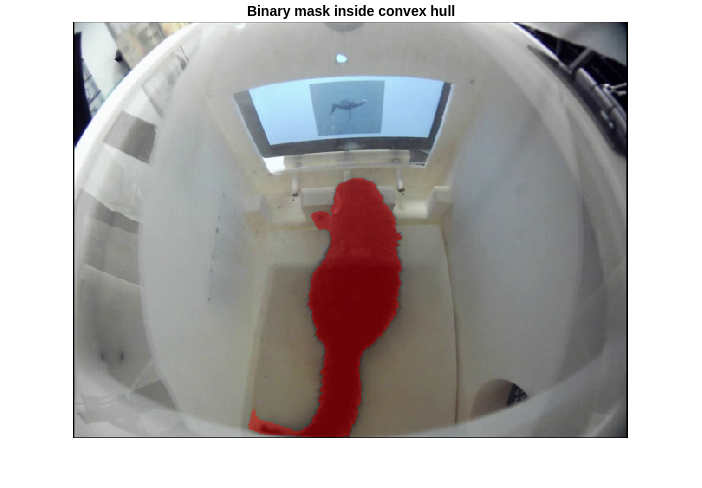

Targets are good. 


[shrewMask_side,shrewMask_cent] = mask_shrew(dlcFrame_side,dlcFrame_cent);

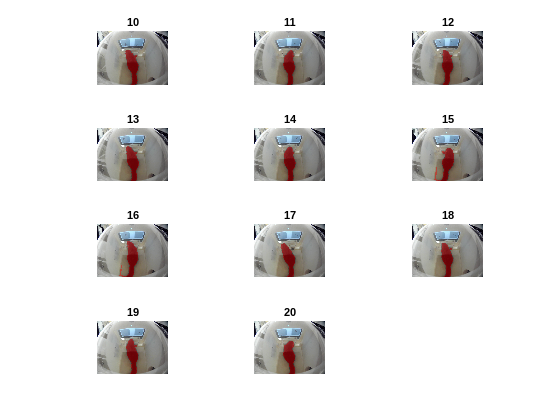

figure(); tiledlayout();
for ii = 10:20
    nexttile;
    I = dlcFrame_side{ii}(:,:,:,round(end/2));
    imshow(labeloverlay(I, shrewMask_side(:,:,ii), 'Colormap', [1 0 0], 'Transparency', 0.6));
    title(ii)
end

allImgs = unique(imageID);
numTr = nan(1,length(allImgs));
for i = 1:length(allImgs)
    numTr(i) = sum(imageID==allImgs(i));
end
im = allImgs(numTr>5);

%1: left, 2: center, 3: right
for i = 1:length(im)
    img = imread(sprintf('../stimulusSets/Camel_v2_test_nn/original/camel_%d.png',im(i)));
    imWidth = size(img,2);
    img_bin = img ~= 127;
    props = regionprops(img_bin, img, 'WeightedCentroid');

    % extract x coordinate of center of mass
    xCent = props.WeightedCentroid(1);
    if xCent<=round(imWidth/3)
        imSide(i) = 1;
    elseif xCent > round(imWidth/3) && xCent <= round(imWidth*2/3)
        imSide(i) = 2;
    elseif xCent > round(imWidth*2/3) && xCent <= imWidth
        imSide(i) = 3;
    end
end

disp(im)

     0     6    13    17    32    38    40    44    55    60    65   132   177



disp(imSide)

     2     1     1     2     2     3     2     2     2     2     2     2     2



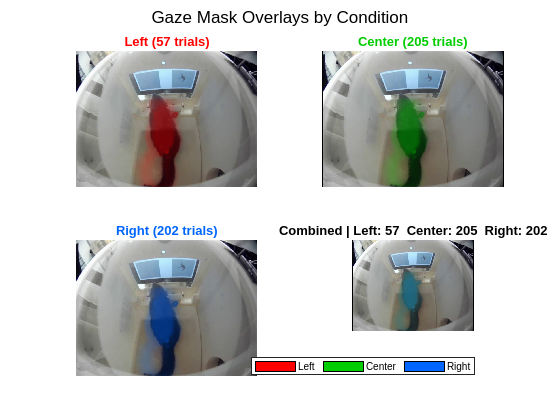

leftImg = [];centImg = [];rightImg = [];
for tr = 1:length(imageID)
    if imSide(im==imageID(tr))==1
        leftImg = cat(3,leftImg,shrewMask_side(:,:,tr));
    elseif imSide(im==imageID(tr))==2
        centImg = cat(3,centImg,shrewMask_side(:,:,tr));
    elseif imSide(im==imageID(tr))==3
        rightImg = cat(3,centImg,shrewMask_side(:,:,tr));
    end
end

% Compute average masks
leftMaskAvg  = mean(leftImg,  3);
centMaskAvg  = mean(centImg,  3);
rightMaskAvg = mean(rightImg, 3);

% Replicate 2D masks to 3D
leftMask3d  = repmat(leftMaskAvg,  [1 1 3]);
centMask3d  = repmat(centMaskAvg,  [1 1 3]);
rightMask3d = repmat(rightMaskAvg, [1 1 3]);

% Normalize image to [0, 1]
img = double(I_side) / 255;

% Define overlay colors and opacity
leftColor  = [1, 0, 0];     % Red
centColor  = [0, 0.8, 0];   % Green
rightColor = [0, 0.4, 1];   % Blue
alpha = 0.5;

% Build colored masks
leftColoredMask  = zeros(size(img));
centColoredMask  = zeros(size(img));
rightColoredMask = zeros(size(img));

for c = 1:3
    leftColoredMask(:,:,c)  = leftColor(c)  * leftMaskAvg;
    centColoredMask(:,:,c)  = centColor(c)  * centMaskAvg;
    rightColoredMask(:,:,c) = rightColor(c) * rightMaskAvg;
end

% Blend each mask separately
blendedLeft  = max(0, min(1, img .* (1 - alpha * leftMask3d)  + leftColoredMask  * alpha));
blendedCent  = max(0, min(1, img .* (1 - alpha * centMask3d)  + centColoredMask  * alpha));
blendedRight = max(0, min(1, img .* (1 - alpha * rightMask3d) + rightColoredMask * alpha));

% Blend all three onto one image sequentially
blendedAll = img;
blendedAll = blendedAll .* (1 - alpha * leftMask3d)  + leftColoredMask  * alpha;
blendedAll = blendedAll .* (1 - alpha * centMask3d)  + centColoredMask  * alpha;
blendedAll = blendedAll .* (1 - alpha * rightMask3d) + rightColoredMask * alpha;
blendedAll = max(0, min(1, blendedAll));

% Get number of trials for each condition
nLeft  = size(leftImg,  3);
nCent  = size(centImg,  3);
nRight = size(rightImg, 3);

% Plot
figure;

% --- Left ---
subplot(2, 2, 1);
imshow(uint8(blendedLeft * 255));
title(sprintf('Left (%d trials)', nLeft), 'Color', leftColor);

% --- Center ---
subplot(2, 2, 2);
imshow(uint8(blendedCent * 255));
title(sprintf('Center (%d trials)', nCent), 'Color', centColor);

% --- Right ---
subplot(2, 2, 3);
imshow(uint8(blendedRight * 255));
title(sprintf('Right (%d trials)', nRight), 'Color', rightColor);

% --- Combined ---
subplot(2, 2, 4);
imshow(uint8(blendedAll * 255));
title(sprintf('Combined | Left: %d  Center: %d  Right: %d', nLeft, nCent, nRight));

% Add legend to combined subplot only
hold on;
hLeft  = patch(NaN, NaN, leftColor);
hCent  = patch(NaN, NaN, centColor);
hRight = patch(NaN, NaN, rightColor);
legend([hLeft, hCent, hRight], {'Left', 'Center', 'Right'}, ...
    'Location', 'southoutside', 'Orientation', 'horizontal');
hold off;

% Overall figure title
sgtitle('Gaze Mask Overlays by Condition');

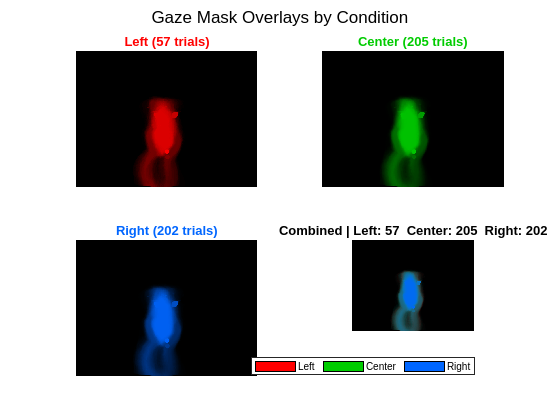

% Compute average masks
leftMaskAvg  = mean(leftImg,  3);
centMaskAvg  = mean(centImg,  3);
rightMaskAvg = mean(rightImg, 3);

% Replicate 2D masks to 3D
leftMask3d  = repmat(leftMaskAvg,  [1 1 3]);
centMask3d  = repmat(centMaskAvg,  [1 1 3]);
rightMask3d = repmat(rightMaskAvg, [1 1 3]);

% Black background the same size as the image
img = zeros(size(I_side, 1), size(I_side, 2), 3);

% Define overlay colors and opacity
leftColor  = [1, 0, 0];     % Red
centColor  = [0, 0.8, 0];   % Green
rightColor = [0, 0.4, 1];   % Blue
alpha = 1.0;                % Full opacity since there's no image underneath

% Build colored masks
leftColoredMask  = zeros(size(img));
centColoredMask  = zeros(size(img));
rightColoredMask = zeros(size(img));

for c = 1:3
    leftColoredMask(:,:,c)  = leftColor(c)  * leftMaskAvg;
    centColoredMask(:,:,c)  = centColor(c)  * centMaskAvg;
    rightColoredMask(:,:,c) = rightColor(c) * rightMaskAvg;
end

% Blend each mask separately onto black background
blendedLeft  = max(0, min(1, img .* (1 - alpha * leftMask3d)  + leftColoredMask  * alpha));
blendedCent  = max(0, min(1, img .* (1 - alpha * centMask3d)  + centColoredMask  * alpha));
blendedRight = max(0, min(1, img .* (1 - alpha * rightMask3d) + rightColoredMask * alpha));

% Blend all three onto black background sequentially
blendedAll = img;
blendedAll = blendedAll .* (1 - alpha * leftMask3d)  + leftColoredMask  * alpha;
blendedAll = blendedAll .* (1 - alpha * centMask3d)  + centColoredMask  * alpha;
blendedAll = blendedAll .* (1 - alpha * rightMask3d) + rightColoredMask * alpha;
blendedAll = max(0, min(1, blendedAll));

% Get number of trials for each condition
nLeft  = size(leftImg,  3);
nCent  = size(centImg,  3);
nRight = size(rightImg, 3);

% Plot
figure;

% --- Left ---
subplot(2, 2, 1);
imshow(blendedLeft);
title(sprintf('Left (%d trials)', nLeft), 'Color', leftColor);

% --- Center ---
subplot(2, 2, 2);
imshow(blendedCent);
title(sprintf('Center (%d trials)', nCent), 'Color', centColor);

% --- Right ---
subplot(2, 2, 3);
imshow(blendedRight);
title(sprintf('Right (%d trials)', nRight), 'Color', rightColor);

% --- Combined ---
subplot(2, 2, 4);
imshow(blendedAll);
title(sprintf('Combined | Left: %d  Center: %d  Right: %d', nLeft, nCent, nRight));

% Add legend to combined subplot only
hold on;
hLeft  = patch(NaN, NaN, leftColor);
hCent  = patch(NaN, NaN, centColor);
hRight = patch(NaN, NaN, rightColor);
legend([hLeft, hCent, hRight], {'Left', 'Center', 'Right'}, ...
    'Location', 'southoutside', 'Orientation', 'horizontal');
hold off;

% Overall figure title
sgtitle('Gaze Mask Overlays by Condition');

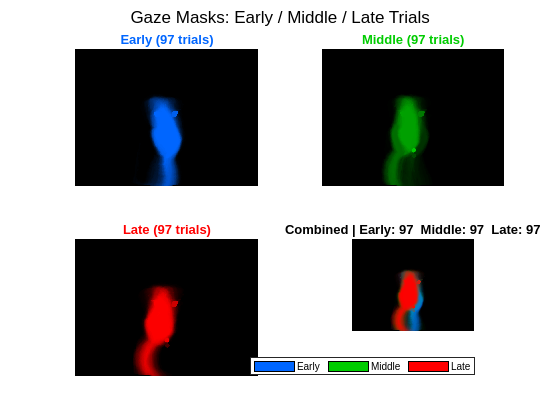

nTrials = size(shrewMask_side, 3);

% Split into thirds by trial index
earlyIdx  = 1 : floor(nTrials/3);
middleIdx = floor(nTrials/3)+1 : floor(2*nTrials/3);
lateIdx   = floor(2*nTrials/3)+1 : nTrials;

% Compute average mask for each third
earlyMaskAvg  = mean(shrewMask_side(:,:,earlyIdx),  3);
middleMaskAvg = mean(shrewMask_side(:,:,middleIdx), 3);
lateMaskAvg   = mean(shrewMask_side(:,:,lateIdx),   3);

% Replicate 2D masks to 3D
earlyMask3d  = repmat(earlyMaskAvg,  [1 1 3]);
middleMask3d = repmat(middleMaskAvg, [1 1 3]);
lateMask3d   = repmat(lateMaskAvg,   [1 1 3]);

% Black background
img = zeros(size(shrewMask_side, 1), size(shrewMask_side, 2), 3);

% Define overlay colors
earlyColor  = [0, 0.4, 1];    % Blue
middleColor = [0, 0.8, 0];    % Green
lateColor   = [1, 0, 0];      % Red
alpha = 1.0;

% Build colored masks
earlyColoredMask  = zeros(size(img));
middleColoredMask = zeros(size(img));
lateColoredMask   = zeros(size(img));

for c = 1:3
    earlyColoredMask(:,:,c)  = earlyColor(c)  * earlyMaskAvg;
    middleColoredMask(:,:,c) = middleColor(c) * middleMaskAvg;
    lateColoredMask(:,:,c)   = lateColor(c)   * lateMaskAvg;
end

% Blend each third separately onto black background
blendedEarly  = max(0, min(1, img .* (1 - alpha * earlyMask3d)  + earlyColoredMask  * alpha));
blendedMiddle = max(0, min(1, img .* (1 - alpha * middleMask3d) + middleColoredMask * alpha));
blendedLate   = max(0, min(1, img .* (1 - alpha * lateMask3d)   + lateColoredMask   * alpha));

% Blend all three onto black background sequentially
blendedAll = img;
blendedAll = blendedAll .* (1 - alpha * earlyMask3d)  + earlyColoredMask  * alpha;
blendedAll = blendedAll .* (1 - alpha * middleMask3d) + middleColoredMask * alpha;
blendedAll = blendedAll .* (1 - alpha * lateMask3d)   + lateColoredMask   * alpha;
blendedAll = max(0, min(1, blendedAll));

% Plot
figure;

% --- Early ---
subplot(2, 2, 1);
imshow(blendedEarly);
title(sprintf('Early (%d trials)', length(earlyIdx)), 'Color', earlyColor);

% --- Middle ---
subplot(2, 2, 2);
imshow(blendedMiddle);
title(sprintf('Middle (%d trials)', length(middleIdx)), 'Color', middleColor);

% --- Late ---
subplot(2, 2, 3);
imshow(blendedLate);
title(sprintf('Late (%d trials)', length(lateIdx)), 'Color', lateColor);

% --- Combined ---
subplot(2, 2, 4);
imshow(blendedAll);
title(sprintf('Combined | Early: %d  Middle: %d  Late: %d', ...
    length(earlyIdx), length(middleIdx), length(lateIdx)));

% Legend on combined subplot
hold on;
hEarly  = patch(NaN, NaN, earlyColor);
hMiddle = patch(NaN, NaN, middleColor);
hLate   = patch(NaN, NaN, lateColor);
legend([hEarly, hMiddle, hLate], {'Early', 'Middle', 'Late'}, ...
    'Location', 'southoutside', 'Orientation', 'horizontal');
hold off;

sgtitle('Gaze Masks: Early / Middle / Late Trials');

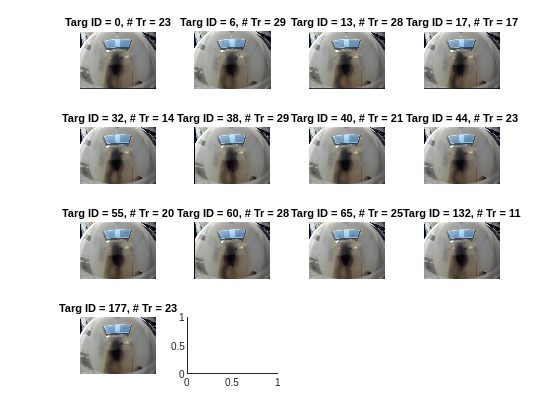

allImgs = unique(imageID);

figure();
tiledlayout('TileSpacing','compact');
nexttile;
for im = 1:length(allImgs)
imgID = allImgs(im);
trIdx = find(imageID==imgID);

avgFrame = nan(size(dlcFrame_side{1},1), size(dlcFrame_side{1},2), size(dlcFrame_side{1},3), length(trIdx));
for ii = 1:length(trIdx)
    trial = trIdx(ii);
    % imshow(dlcFrame{trial}(:,:,:,round(end/2)));
    avgFrame(:,:,:,ii) = dlcFrame_side{trial}(:,:,:,round(end/2));
end

posAvg = mean(avgFrame,4);
imshow(uint8(posAvg))
title(sprintf('Targ ID = %d, # Tr = %d', imgID, length(trIdx)))
nexttile;
end

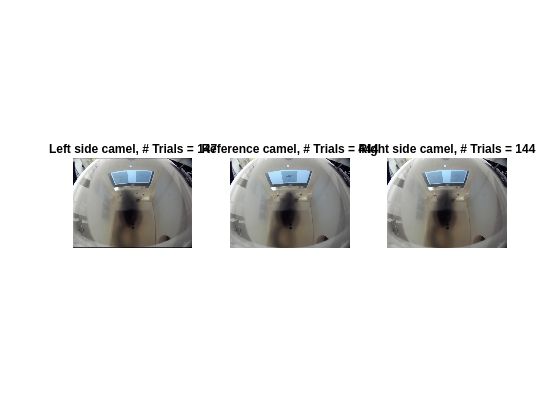

left_camel = [];
right_camel = [];
for tr = 1:length(camel_side)
    if camel_side(tr)==1
        left_camel = cat(4, left_camel, dlcFrame_side{tr}(:,:,:,round(end/2)));
    elseif camel_side(tr)==2
        right_camel = cat(4, right_camel, dlcFrame_side{tr}(:,:,:,round(end/2)));
    end
end

center_camel = [];
for tr = 1:length(cent_on)
    center_camel = cat(4, center_camel, dlcFrame_cent{tr}(:,:,:,round(end/2)));
end

figure;
subplot(1,3,1)
imshow(uint8(mean(left_camel,4)))
title(sprintf('Left side camel, # Trials = %d', size(left_camel,4)))
subplot(1,3,2)
imshow(uint8(mean(center_camel,4)))
title(sprintf('Reference camel, # Trials = %d', size(center_camel,4)))
subplot(1,3,3)
imshow(uint8(mean(right_camel,4)))
title(sprintf('Right side camel, # Trials = %d', size(right_camel,4)))

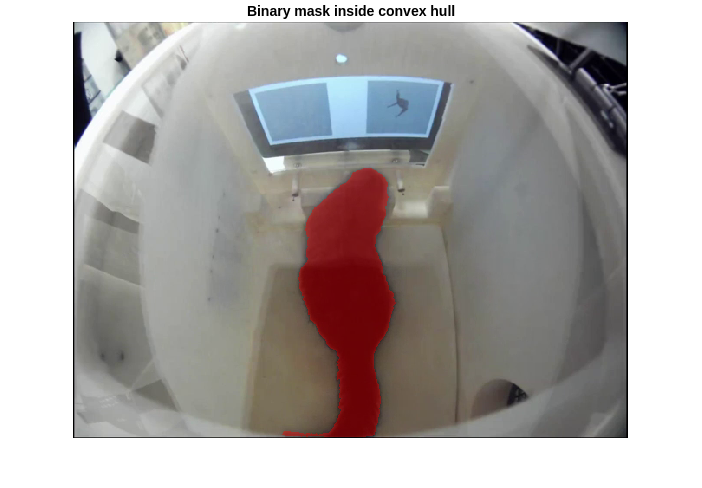

Targets are good. 


left_camel = {}; lt = 1; left_tr=[];
right_camel = {}; rt = 1; right_tr=[];
for tr = 1:length(camel_side)
    if camel_side(tr)==1
        left_camel{lt} = dlcFrame_side{tr}(:,:,:,round(end/2));
        left_tr = [left_tr, tr];
        lt = lt+1;
    elseif camel_side(tr)==2
        right_camel{rt} = dlcFrame_side{tr}(:,:,:,round(end/2));
        right_tr = [right_tr, tr];
        rt = rt+1;
    end
end

center_camel = [];
for tr = 1:length(cent_on)
    center_camel{tr} = dlcFrame_cent{tr}(:,:,:,round(end/2));
end

[shrewMask_left,shrewMask_right] = mask_shrew(left_camel,right_camel);

half_tr = round(length(camel_side)/2);
shrew_early_left = shrewMask_left(:,:,left_tr<half_tr);
shrew_late_left = shrewMask_left(:,:,left_tr>=half_tr);
shrew_early_right = shrewMask_right(:,:,right_tr<half_tr);
shrew_late_right = shrewMask_right(:,:,right_tr>=half_tr);

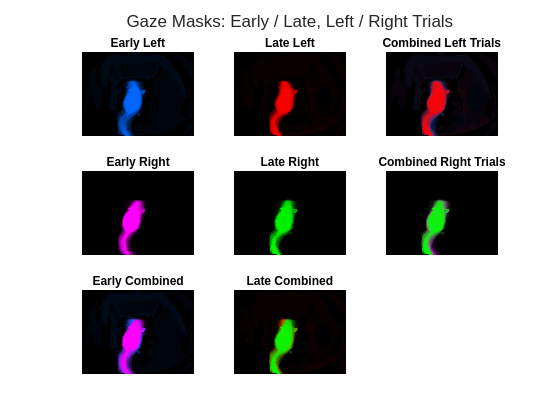

% Define overlay colors
earlyLeftColor  = [0, 0.4, 1];    % Blue
lateLeftColor   = [1, 0, 0];      % Red
earlyRightColor  = [1, 0, 1];    % Magenta
lateRightColor   = [0, 1, 0];      % Green
alpha = 1.0;

% Build colored masks
earlyLeftMask  = zeros(size(img));
lateLeftMask   = zeros(size(img));
earlyRightMask  = zeros(size(img));
lateRightMask   = zeros(size(img));

for c = 1:3
    earlyLeftMask(:,:,c)  = earlyLeftColor(c)  * mean(shrew_early_left,3);
    lateLeftMask(:,:,c)   = lateLeftColor(c)   * mean(shrew_late_left,3);
    earlyRightMask(:,:,c)  = earlyRightColor(c)  * mean(shrew_early_right,3);
    lateRightMask(:,:,c)   = lateRightColor(c)   * mean(shrew_late_right,3);
end

earlyLeftMask3d  = repmat(mean(shrew_early_left,3),  [1 1 3]);
lateLeftMask3d  = repmat(mean(shrew_late_left,3),  [1 1 3]);
earlyRightMask3d  = repmat(mean(shrew_early_right,3),  [1 1 3]);
lateRightMask3d  = repmat(mean(shrew_late_right,3),  [1 1 3]);

% Blend each third separately onto black background
blendedLeftEarly  = max(0, min(1, img .* (1 - alpha * earlyLeftMask3d)  + earlyLeftMask  * alpha));
blendedLeftLate   = max(0, min(1, img .* (1 - alpha * lateLeftMask3d)   + lateLeftMask   * alpha));
blendedRightEarly  = max(0, min(1, img .* (1 - alpha * earlyRightMask3d)  + earlyRightMask  * alpha));
blendedRightLate   = max(0, min(1, img .* (1 - alpha * lateRightMask3d)   + lateRightMask   * alpha));

% Blend all three onto black background sequentially
blendedLeftAll = img;
blendedLeftAll = blendedLeftAll .* (1 - alpha * earlyLeftMask3d)  + blendedLeftEarly  * alpha;
blendedLeftAll = blendedLeftAll .* (1 - alpha * lateLeftMask3d) + blendedLeftLate * alpha;
blendedLeftAll = max(0, min(1, blendedLeftAll));
blendedRightAll = img;
blendedRightAll = blendedRightAll .* (1 - alpha * earlyRightMask3d)   + blendedRightEarly   * alpha;
blendedRightAll = blendedRightAll .* (1 - alpha * lateRightMask3d)   + blendedRightLate   * alpha;
blendedRightAll = max(0, min(1, blendedRightAll));

blendedEarlyAll = img;
blendedEarlyAll = blendedEarlyAll .* (1 - alpha * earlyLeftMask3d)  + blendedLeftEarly  * alpha;
blendedEarlyAll = blendedEarlyAll .* (1 - alpha * earlyRightMask3d) + blendedRightEarly * alpha;
blendedEarlyAll = max(0, min(1, blendedEarlyAll));
blendedLateAll = img;
blendedLateAll = blendedLateAll .* (1 - alpha * lateLeftMask3d)  + blendedLeftLate  * alpha;
blendedLateAll = blendedLateAll .* (1 - alpha * lateRightMask3d) + blendedRightLate * alpha;
blendedLateAll = max(0, min(1, blendedLateAll));

% Plot
figure;
tiledlayout(3,3,'TileSpacing','tight')

% --- Early Left ---
nexttile;
imshow(blendedLeftEarly);
title('Early Left');

% --- Late Left ---
nexttile;
imshow(blendedLeftLate);
title('Late Left');

% --- Combined ---
nexttile;
imshow(blendedLeftAll);
title('Combined Left Trials');

% --- Early Right ---
nexttile;
imshow(blendedRightEarly);
title('Early Right');

% --- Late Right ---
nexttile;
imshow(blendedRightLate);
title('Late Right');

% --- Combined ---
nexttile;
imshow(blendedRightAll);
title('Combined Right Trials');

% --- Early Combined ---
nexttile;
imshow(blendedEarlyAll);
title('Early Combined');

% --- Late Combined ---
nexttile;
imshow(blendedLateAll);
title('Late Combined');

sgtitle('Gaze Masks: Early / Late, Left / Right Trials');